## Changing in Stimulus Parameters

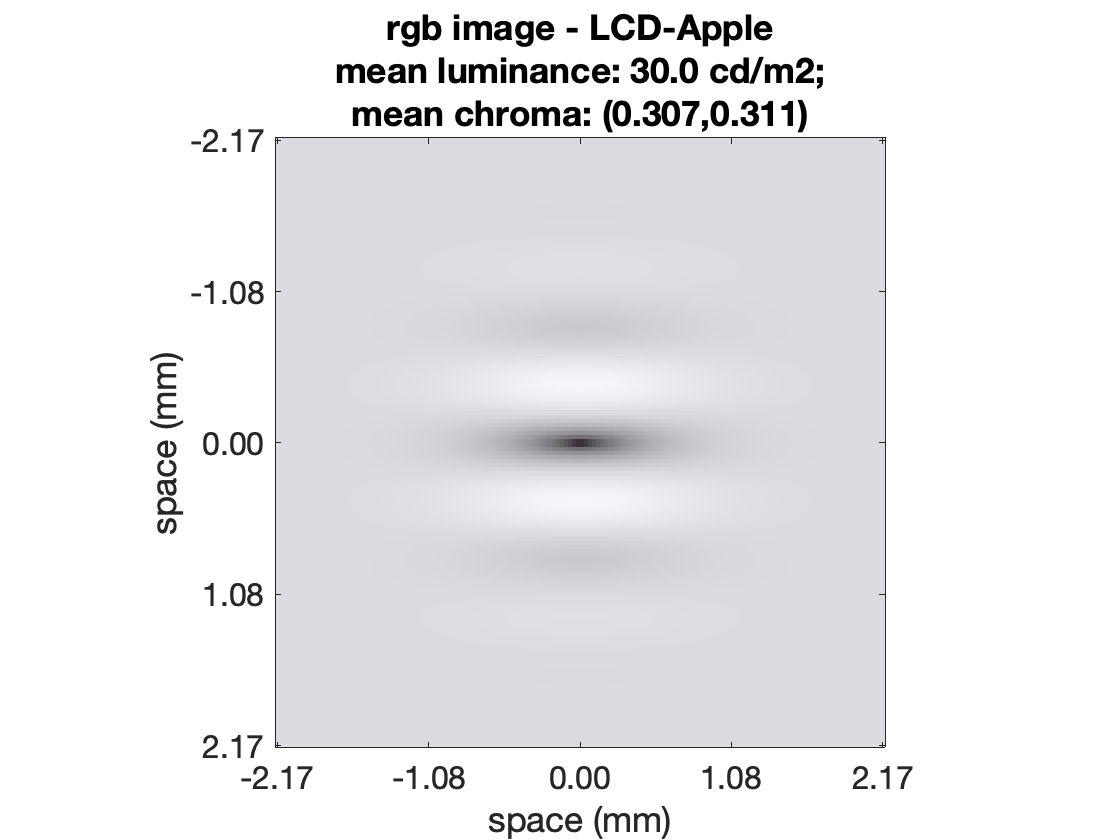

presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.50);
% influence of spatial phase degrees on the stimulus display
stimParams = struct(...
'spatialFrequencyCyclesPerDeg', 10, ... 
'orientationDegs',90, ...              
'phaseDegs',180, ...                     % spatial phase degrees
'sizeDegs',0.5, ...                    
'sigmaDegs',0.2/3, ...                 % sigma of Gaussian envelope, in degrees
'contrast',1,...                     % 0.9 Michelson contrast
'meanLuminanceCdPerM2', 30, ...         % 40 cd/m2 mean luminance
'pixelsAlongWidthDim', [], ...          
'pixelsAlongHeightDim', [] ...          
);
scene1 = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 15);
% Visualize the generated scene
visualizeScene(scene1, ...
    'displayRadianceMaps', false);

## Changing Parameters for the Human eye model

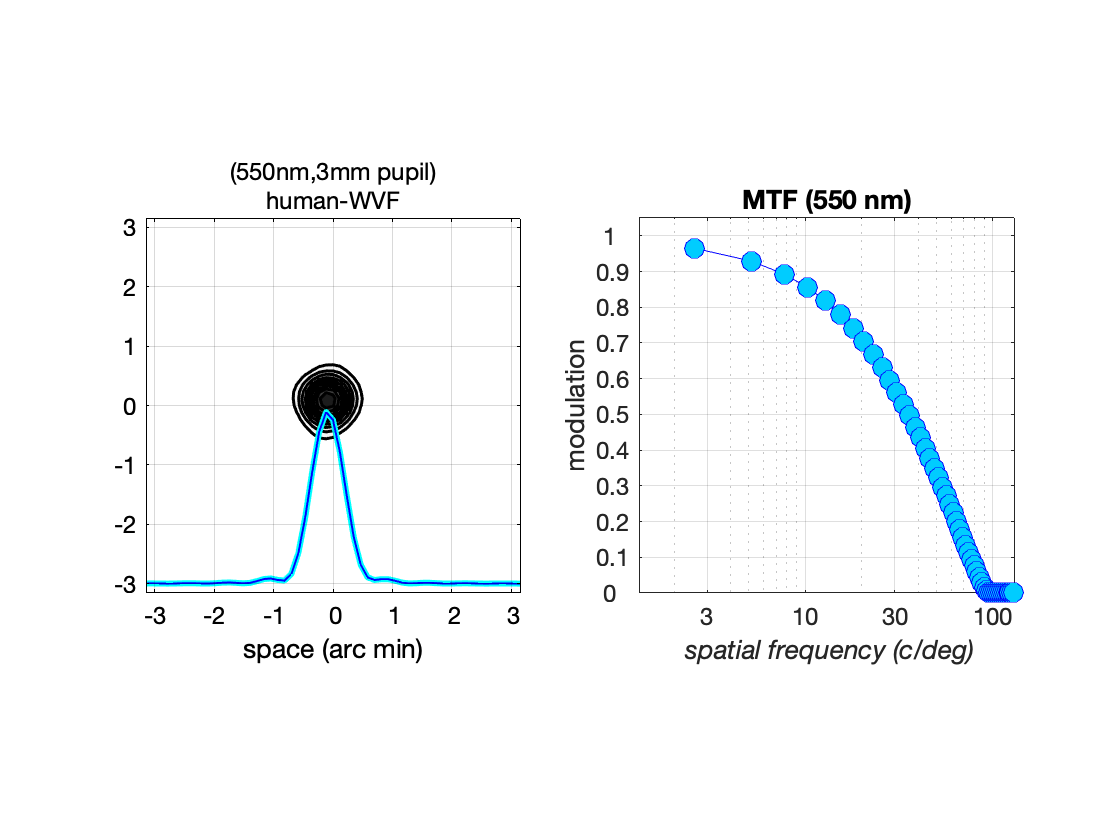

% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

% Visualize the PSFs and OTFs
testSpatialSupportArcMin = 6; % 6
testSpatialSfrequencyCPD = 130; % 120
targetwavelength = 550; %550

% Visualize the PSF/OTF at 550 (in-focus)
visualizeOptics(theOI, targetwavelength, testSpatialSupportArcMin, testSpatialSfrequencyCPD);